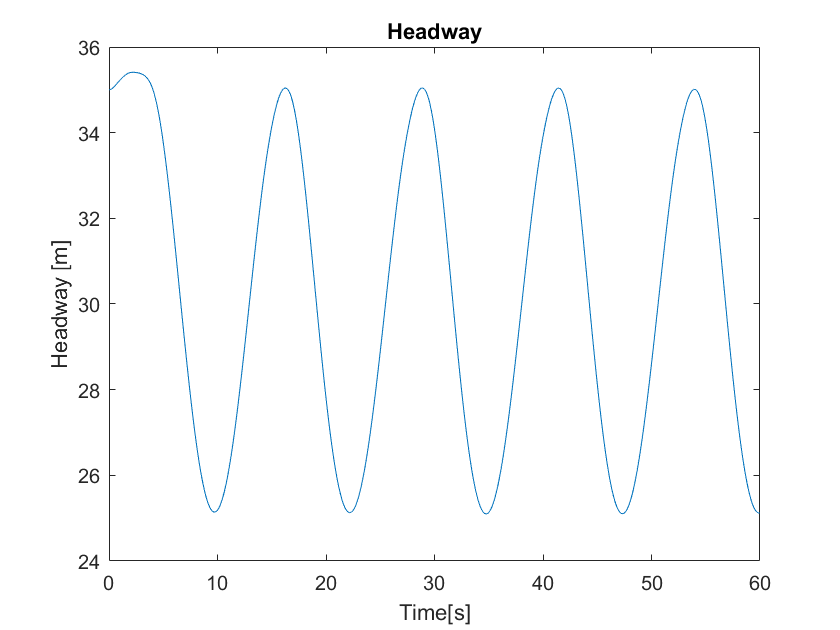

%Code for Adaptive Cruise Control of a vehicle using a PI controller.
%OUTPUT : Headway Between two vehicles
%INPUT : Leader's Velocity

clear all; close all;
% Parameters Reference ME542 HW3 Q4.
a = 0.1;
b = 0;
c = 0.0005;
v_max = 30;
h_go = 35;
h_stop = 5; 
v_l_star = 25;
v_l_amp = 6;
omega = 0.5;

k_p = 0.5;
k_i = 0.5; 
k_v = 0.5;

tstart = 0;
tstop = 60;
tspan = tstart:0.1:tstop;
y0 = [35 25 0]; % Initial Condition of h,v,z.
                % Initial Condition for h and v are taken as their steady state values.

[t,y] = ode45(@(t,y)odefunc(t,y,a,b,c,v_max,h_go,h_stop,...
                            k_p,k_i,k_v,v_l_star,v_l_amp,omega),tspan,y0);

figure(1);
plot(t,y(:,1));
xlabel("Time[s]");
ylabel("Headway [m]");
title("Headway");

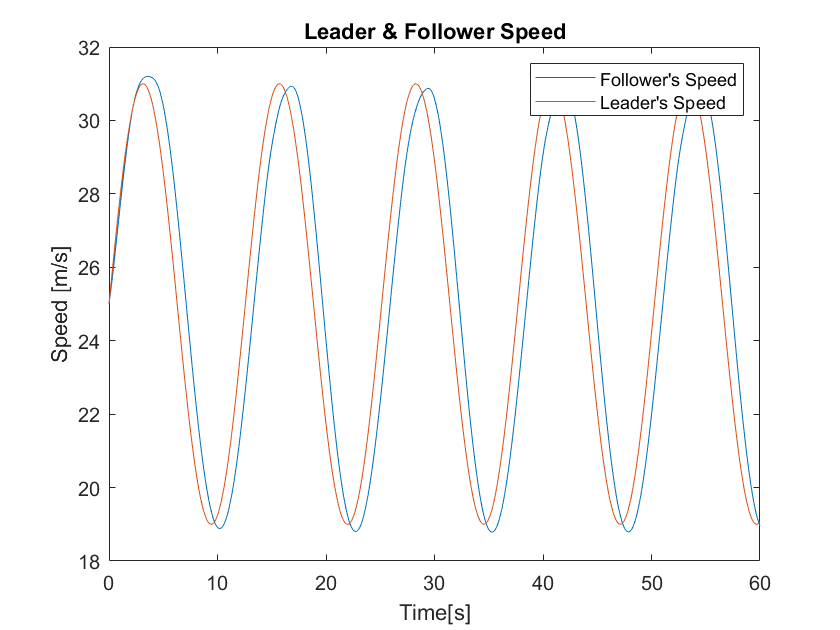

saveas(gcf,"Output_Graphs\PIV_Controller_for_Adaptive_Cruise_Control\Headway.jpg");

v_l = v_l_star + v_l_amp*sin(omega*t);
figure(2);hold on;box on;
plot(t,y(:,2));
plot(t,v_l);
xlabel("Time[s]");
ylabel("Speed [m/s]");
title("Leader & Follower Speed");
legend("Follower's Speed","Leader's Speed");

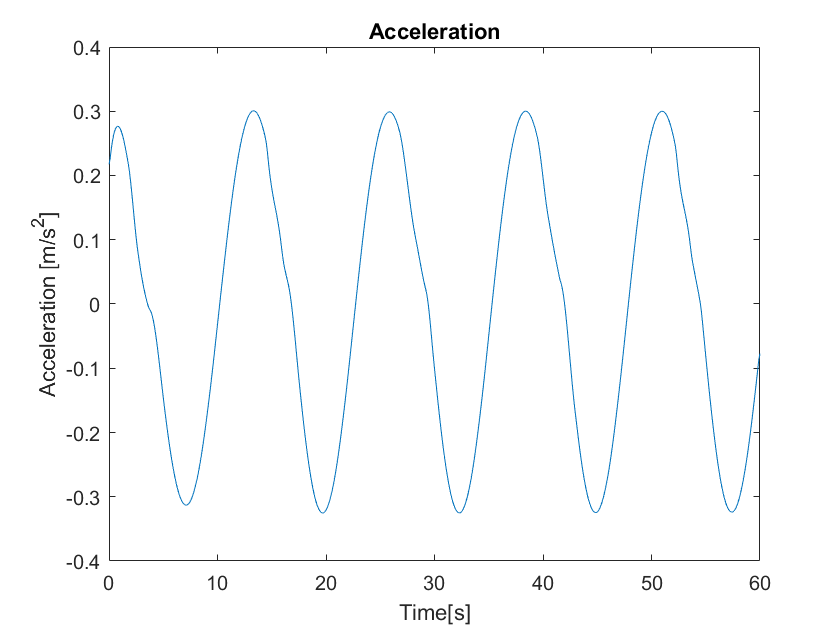

saveas(gcf,"Output_Graphs\PIV_Controller_for_Adaptive_Cruise_Control\Leader_&_Follower_Speed.jpg");

figure(3);hold on; box on;
acceleration = gradient(y(:,2));
plot(t,acceleration);
xlabel("Time[s]");
ylabel("Acceleration [m/s^2]");
title("Acceleration");

saveas(gcf,"Output_Graphs\PIV_Controller_for_Adaptive_Cruise_Control\Acceleration.jpg");



function dydt = odefunc(t,y,a,b,c,v_max,h_go,h_stop,k_p,k_i,k_v,v_l_star,v_l_amp,omega)

v_l = v_l_star + v_l_amp*sin(omega*t); %Given

dydt(1) = v_l - y(2);
dydt(2) = -a - b*y(2) - c*(y(2)^2) +...
          k_p*(RangePolicy(v_max,h_go,h_stop,y)-y(2)) +...
          k_i*y(3) +...
          k_v*(SaturationFunction(v_l,v_max)-y(2));
dydt(3) = RangePolicy(v_max,h_go,h_stop,y) - y(2);

dydt = dydt';
end

% function V = RangePolicy(v_max,h_go,h_stop,y)
%     V= v_max*(h_go<=y(1)) +...
%        v_max*((y(1)-h_go)/(h_go-h_stop))*(h_stop<y(1) && y(1)<h_go);
% end
% 
% function W = SaturationFunction(v_l,v_max)
%     W = v_l*(v_l<v_max) + v_max*(v_l>=v_max);
% end

function V = RangePolicy(v_max,h_go,h_stop,y)
    if y(1)<= h_stop
            V = 0;
    elseif h_stop <y(1) && y(1)< h_go
            V = v_max*(y(1)-h_stop)/(h_go-h_stop);
    else 
            V = v_max;
    end    
end

function W = SaturationFunction(v_l,v_max)
    if v_l <v_max
        W = v_l;
    else
        W = v_max;
    end
end

%Different plot for different way of writing RangePolicy and
%SaturationFunction.